# Dendritic Tree Approximations - Plots (180497C)

## Defining the variables (from cable.m)

% Dimensions of compartments

d1 = 75e-4; 			% cm
d21 = 30e-4; 			% cm
d22 = 15e-4; 			% cm
%d21 = 47.2470e-4;       % E9 cm
%d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

## Question 03

%Finding the solutions of the system Ax = b
x = A\b

x =    0.000736975648372
   0.000016722595446
   0.001129071096534
  -0.000002798687438
   0.001129071096534
  -0.000002798687438


## Question 04

The values used in this section are from the calculations in question 03 (from the code in cable.m). 

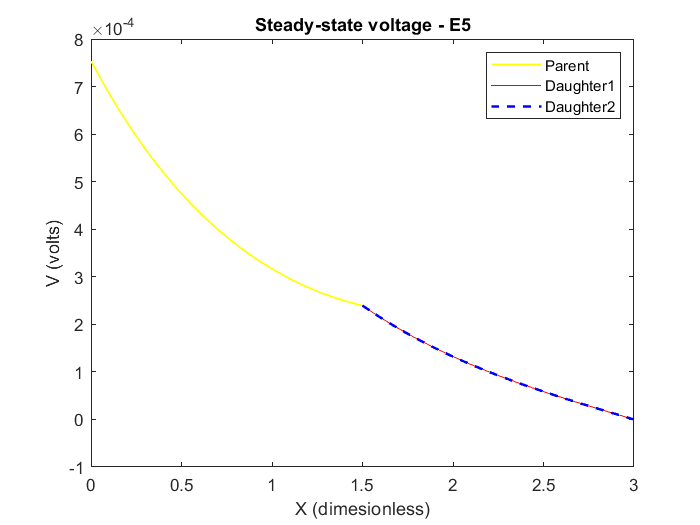

y1 = linspace(0,l1, 20);
y21 = linspace(l1,l21, 20);
y22 = linspace(l1,l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

p = plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b--');
p(1).LineWidth = 1;
p(2).LineWidth = 0.5;
p(3).LineWidth = 1.5;
xlabel('X (dimesionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend('Parent','Daughter1', 'Daughter2')

## Section 04

(a)

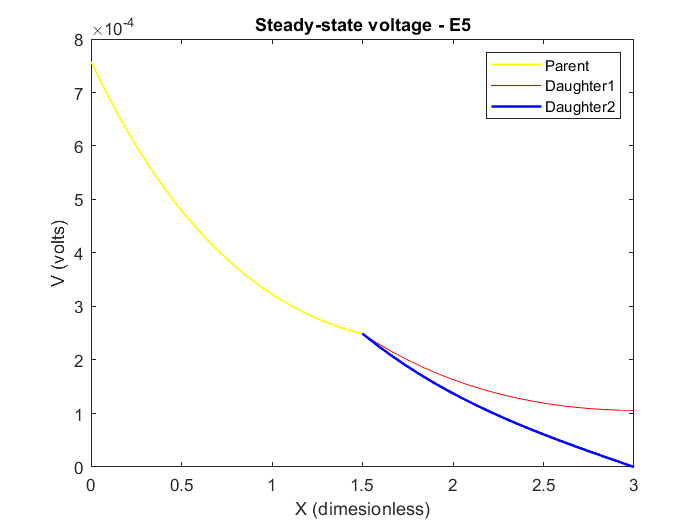

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];

%Finding the solutions of the system Ax = b
x = A\b;


y1 = linspace(0,l1, 20);
y21 = linspace(l1,l21, 20);
y22 = linspace(l1,l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

p = plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
p(1).LineWidth = 1;
p(2).LineWidth = 0.5;
p(3).LineWidth = 1.5;
xlabel('X (dimesionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend('Parent','Daughter1', 'Daughter2')

(b)

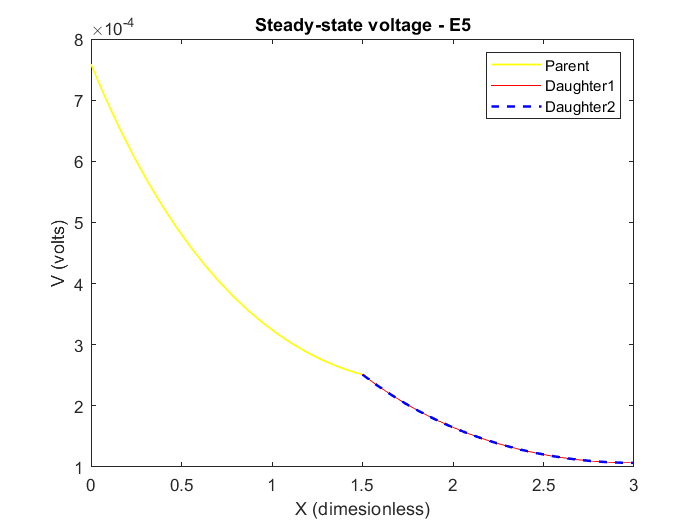

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
A(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];

%Finding the solutions of the system Ax = b
x = A\b;


y1 = linspace(0,l1, 20);
y21 = linspace(l1,l21, 20);
y22 = linspace(l1,l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

p = plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b--');
p(1).LineWidth = 1;
p(2).LineWidth = 0.5;
p(3).LineWidth = 1.5;
xlabel('X (dimesionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend('Parent','Daughter1', 'Daughter2')

(c)

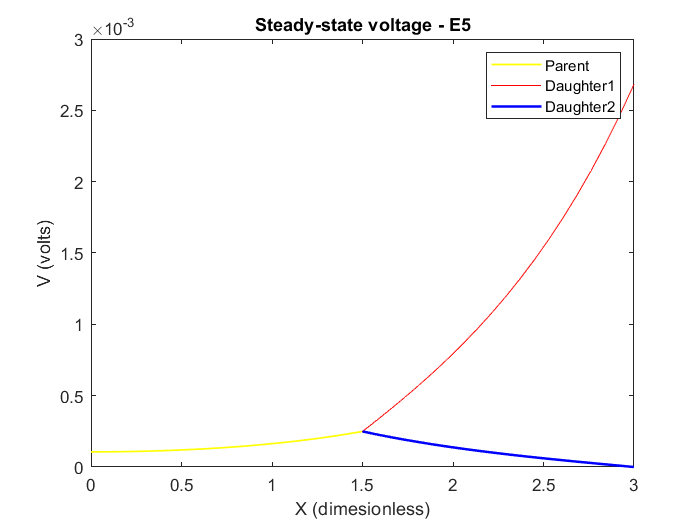

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

A(2,:) = [ 0 0 -exp(-l21) exp(l21) 0 0];
b(1) = 0;
b(2) = rl21*iapp;

%Finding the solutions of the system Ax = b
x = A\b;


y1 = linspace(0,l1, 20);
y21 = linspace(l1,l21, 20);
y22 = linspace(l1,l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

p = plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
p(1).LineWidth = 1;
p(2).LineWidth = 0.5;
p(3).LineWidth = 1.5;
xlabel('X (dimesionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend('Parent','Daughter1', 'Daughter2')

(d)

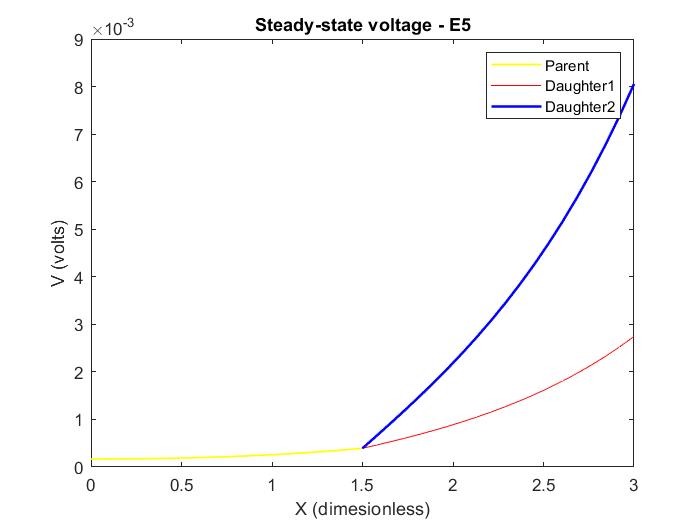

b(3) = rl22*iapp;

%Finding the solutions of the system Ax = b
x = A\b;


y1 = linspace(0,l1, 20);
y21 = linspace(l1,l21, 20);
y22 = linspace(l1,l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

p = plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
p(1).LineWidth = 1;
p(2).LineWidth = 0.5;
p(3).LineWidth = 1.5;
xlabel('X (dimesionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend('Parent','Daughter1', 'Daughter2')

## Question 06

%Redefining some variables for question (06)
d21 = 47.2470e-4;       % E9 cm
d22 = d21;               % E9 cm
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


%Using the default values for A and b
A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';



2(b)

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
A(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];

%Finding the solutions of the system Ax = b
x = A\b

x = 	1.0e+-3 *

   0.721600900025872
   0.001347847100187
   0.713166655679503
   0.001767763400091
   0.713166655679503
   0.001767763400091


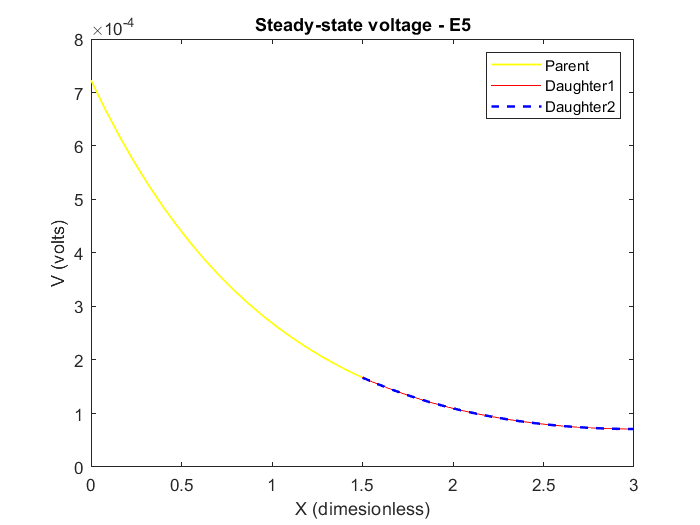

y1 = linspace(0,l1, 20);
y21 = linspace(l1,l21, 20);
y22 = linspace(l1,l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

p = plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b--');
p(1).LineWidth = 1;
p(2).LineWidth = 0.5;
p(3).LineWidth = 1.5;
xlabel('X (dimesionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend('Parent','Daughter1', 'Daughter2')

2(d)

%Changing the values of A and b

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
b(1) = 0;
b(2) = rl21*iapp;
b(3) = rl22*iapp;

%Finding the solutions of the system Ax = b
x = A\b

x = 	1.0e+-3 *

   0.054143597266040
   0.054143597266040
  -0.284687339096084
   0.071012996259849
  -0.284687339096083
   0.071012996259849


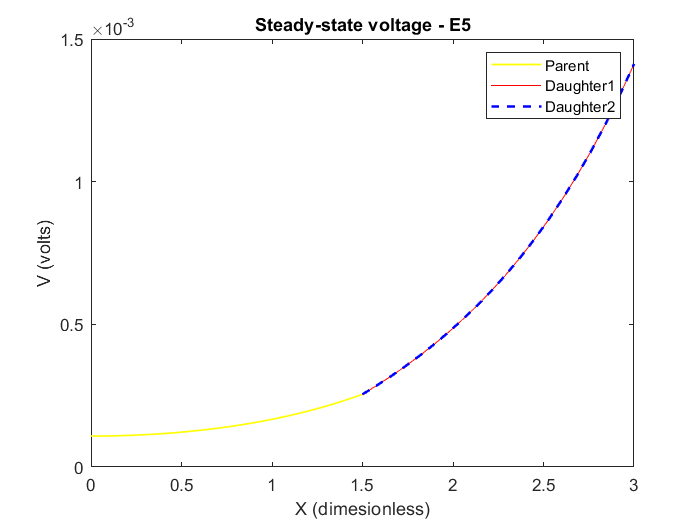

y1 = linspace(0,l1, 20);
y21 = linspace(l1,l21, 20);
y22 = linspace(l1,l22, 20);
v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

p = plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b--');
p(1).LineWidth = 1;
p(2).LineWidth = 0.5;
p(3).LineWidth = 1.5;
xlabel('X (dimesionless)')
ylabel('V (volts)')
title('Steady-state voltage - E5')
legend('Parent','Daughter1', 'Daughter2')